I = imread('62x_Salac_Pa14wt_SaPa14wt=1-1,1-10,100-1,10-1_co_SCFM2_tile2x2_3-13-19_z25_t17_p3_m3.tif');
%I = imread('rose.tif');
Ir = squeeze(I(:,:,1));
Ig = squeeze(I(:,:,2));
[hrCounts, hrBins]= imhist(im2double(Ir))

hrCounts =       145232
       77768
       25937
        8203
        2670
        1067
         446
         254
         124
          72


hrBins =          0
    0.0039
    0.0078
    0.0118
    0.0157
    0.0196
    0.0235
    0.0275
    0.0314
    0.0353


[hgCounts, hgBins] = imhist(Ig)

hgCounts =        18132
       11757
       12592
       12956
       12918
       12328
       11775
       11347
       10650
        9933


hgBins =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



%IgAdj = imadjust(Ig);
%IrAdj = imadjust(Ir);
%matIg = mat2gray(Ig);
%matIr = mat2gray(Ir);
[rawThreshG, rawEffG] = graythresh(Ig)
[adjThreshG, adjEffG] = graythresh(IgAdj)

rawThreshG = 0.0784

rawEffG = 0.6499

[matThreshG, matEffG] = graythresh(matIg)

adjThreshG = 0.3353

adjEffG = 0.6803

[rawThreshR, rawEffR] = graythresh(Ir)

matThreshG = 0.1275

matEffG = 0.6511

[adjThreshR, adjEffR] = graythresh(IrAdj)

rawThreshR = 0.0039

rawEffR = 0.4150

[matThreshR, matEffR] = graythresh(matIr)

adjThreshR = 0.3745

adjEffR = 0.6795

low  = stretchlim(Ir)

matThreshR = 0.0039

matEffR = 0.3921

lowhigh = stretchlim(Ig)

lowhigh =          0
    0.0157


hisRaw = histogram(im2double(Ir))

lowhigh =          0
    0.2275


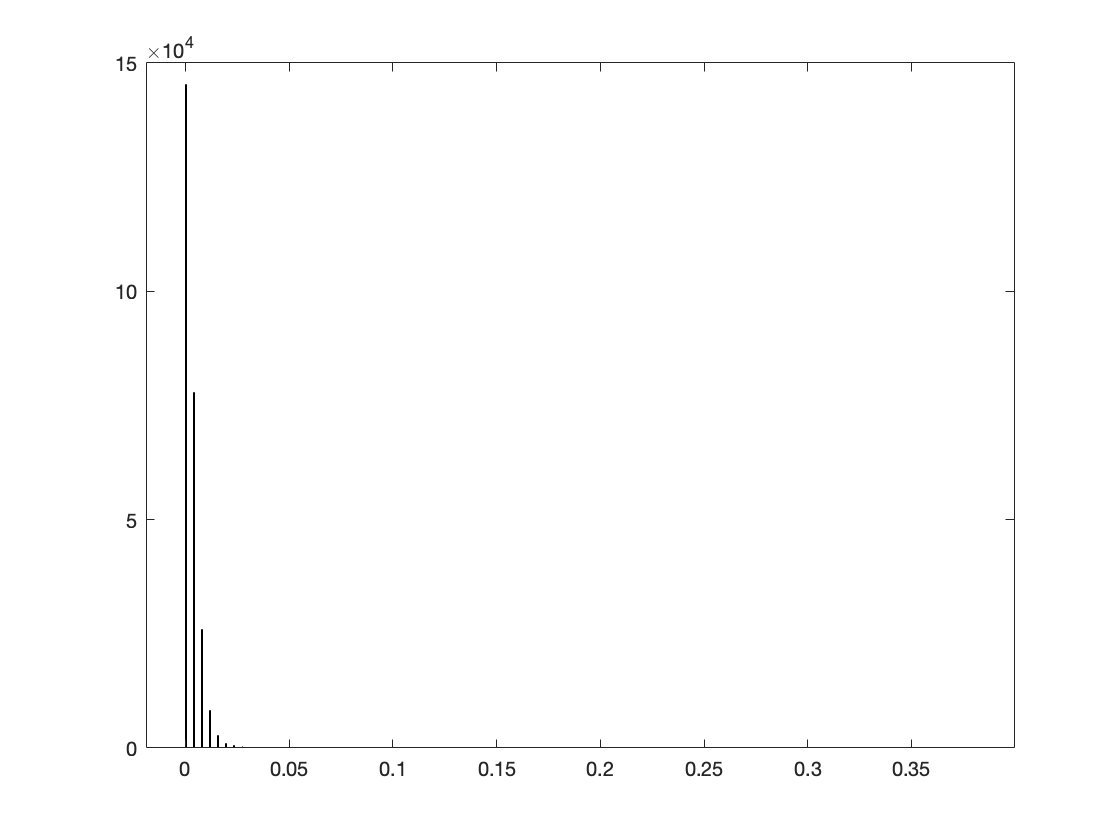

hisRaw =   Histogram with properties:

             Data: [512×512 double]
           Values: [1×1268 double]
          NumBins: 1268
         BinEdges: [1×1269 double]
         BinWidth: 3.0000e-04
        BinLimits: [0 0.3804]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


hiMat = histogram(matIr)

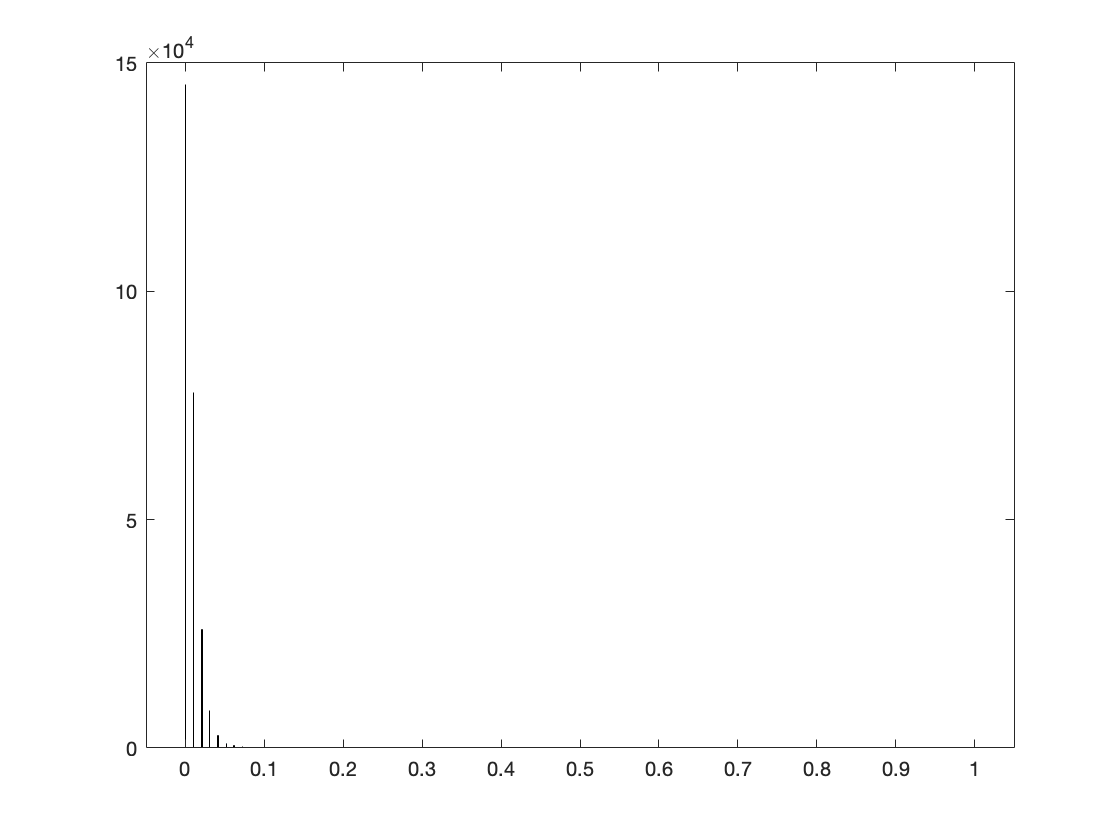

hiMat =   Histogram with properties:

             Data: [512×512 double]
           Values: [1×2000 double]
          NumBins: 2000
         BinEdges: [1×2001 double]
         BinWidth: 5.0000e-04
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


histogram(im2double(Ir))

histogram(IrAdj)

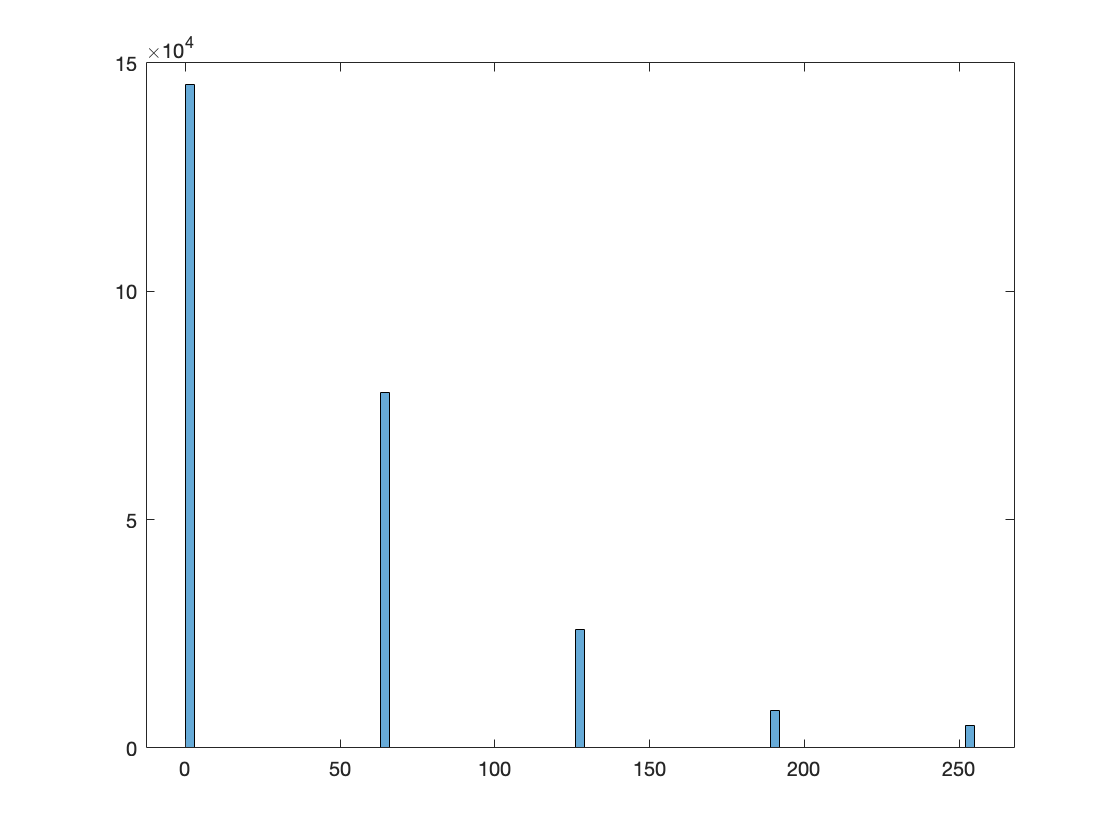

figure,imshow(matIr)

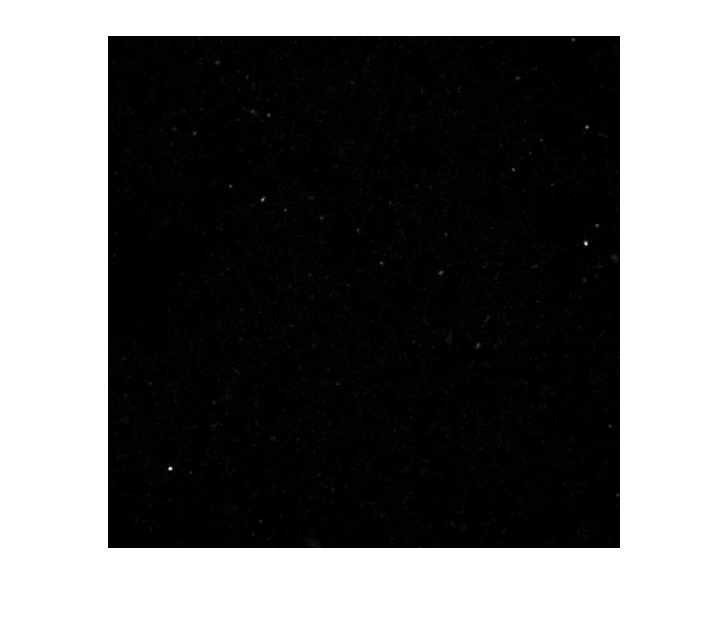

figure,imshow(Ir)

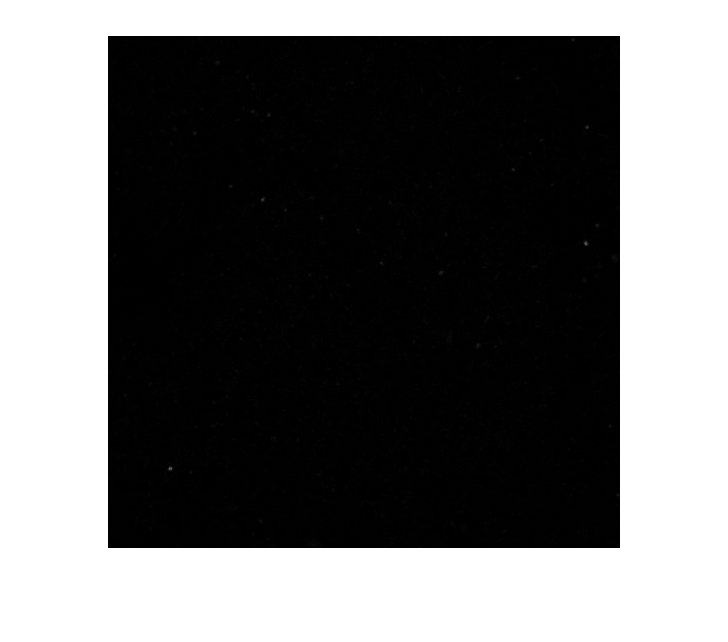

mean(Ir)

I = imread('62x_Salac_Pa14wt_SaPa14wt=1-1,1-10,100-1,10-1_co_SCFM2_tile2x2_3-13-19__z0_t2_p3_m2.tif');